# **Project 3 - Low Discrepancy Sequences and Simulation of Stochastic Processes**

**1. Evaluate the following expected values and probabilities: **

$\textrm{p1}=P\left(Y_2 >5\right),\;$$\textrm{e1}=E\left(X_2^{\frac{1}{3}} \right),\;\textrm{e2}=E\left(Y_3 \right),\textrm{e3}=E\left(X_2 Y_2 \;\;1\left(X_2 >1\right)\right)$**,**

**where the Ito’s processes X and Y evolve according to the following SDEs:**


$$dX_t =\left(\frac{1}{5}-\frac{1}{2}X_t \right)\textrm{dt}+\frac{2}{3}dW_t ,\;X_0 =1;$$
   
$$dY_t =\left(\left(\frac{2}{1+t}\right)Y_t -\frac{1+t^3 }{3}\right)\textrm{dt}+\frac{1+t^3 }{3}dZ_t ,\;Y_0 =\frac{3}{4},$$


**and W, Z are independent Wiener Processes.**

**Inputs: **$X_0 ,\;Y_0$

**Outputs: Values: p1, e1, e2, e3.  **

rng(100);
n=100000; dt=0.001; T=3; % note: dt is delta time
% X0, Y0
X0 = 1;
Y0 = 3/4;
% number of steps
num_steps = T/dt;
% note: Xt_vector(1) = X0; Yt_vector(1) = Y0;
Xt_vector = ones(num_steps+1,n); Xt_vector(1,:) = ones(1,n) * X0;
Yt_vector = ones(num_steps+1,n); Yt_vector(1,:) = ones(1,n) * Y0;
for t = 1:num_steps
    % Wiener Processes
    Wt = normrnd(0,sqrt(dt),[1,n]);
    Zt = normrnd(0,sqrt(dt),[1,n]);
    % dX = (1/5 -1/2 Xt)dt + 2/3 dWt
    Xt_vector(t+1,:) = Xt_vector(t,:) + (1/5 -1/2 * Xt_vector(t,:))*dt + 2/3 * Wt;
    % dY = (2/(1+t) Yt + (1+t^3)/3)dt + (1+t^3)/3 dZt
    Yt_vector(t+1,:) = Yt_vector(t,:) + (2/(1+(t-1)*dt) * Yt_vector(t,:) + (1+((t-1)*dt)^3)/3)*dt + (1+((t-1)*dt)^3)/3 * Zt;
end

% output p1, e1, e2, e3
% p1 = P(Y2>5)
Y2 = Yt_vector(2/dt+1,:);
p1 = sum(Y2>5)/length(Y2)

p1 = 0.9766

% e1 = E(X2^(1/3))
X2 = Xt_vector(2/dt+1,:);
e1 = mean(nthroot(X2,3),2)

e1 = 0.6396

% e2 = E(Y3)
Y3 = Yt_vector(3/dt+1,:);
e2 = mean(Y3,2)

e2 = 26.1443

% e3 = E(X2Y2 1(X2>1))
e3 = mean(X2.*Y2.*(X2>1),2)

e3 = 3.9217

**2. Estimate the following expected values:  **


$$\textrm{e1}=E{\left(1+X_2 \right)}^{\frac{1}{3}} ,\;\textrm{e2}=E\left(X_1 Y_1 \right),$$


**where **$dX_t =\frac{1}{4}X_t \;\textrm{dt}+\frac{1}{3}X_t \;dW_t -\frac{3}{4}X_t \;dZ_t ,\;X_0 =1;$   $Y_t =e^{-0\ldotp 08t+\frac{1}{3}W_t +\frac{3}{4}Z_t } ,$

**and W, Z are independent Wiener Processes.**

**Inputs: **$X_0$

**Outputs: Values: e*****1*****, *****e2***  

% set seed
rng(9001);
n=100000; dt =0.001; T=3; % note: dt is delta time
% X0, Y0
X0 = 1;
Y0 = 1; % set Y0=1, which has no influence on Yi where i>=1

% number of steps
num_steps = T/dt;
% note: Xt_vector(1) = X0; Yt_vector(1) = Y0;
Xt_vector = ones(num_steps+1,n); Xt_vector(1,:) = ones(1,n) * X0;
Yt_vector = ones(num_steps+1,n); Yt_vector(1,:) = ones(1,n) * Y0;
for t = 1:num_steps
    % Wiener Processes
    delta_Wt = normrnd(0,sqrt(dt),[1,n]);
    delta_Zt = normrnd(0,sqrt(dt),[1,n]);
    if t == 1
        Wt = delta_Wt;
        Zt = delta_Zt;
    else
        Wt = Wt + delta_Wt;
        Zt = Zt + delta_Zt;
    end
    % dX = 1/4 Xt dt + 1/3 Xt dWt - 3/4 Xt dZt
    Xt_vector(t+1,:) = Xt_vector(t,:) + 1/4 * Xt_vector(t,:) * dt + 1/3 * Xt_vector(t,:) .* delta_Wt - 3/4 * Xt_vector(t,:) .* delta_Zt;
    % dY = exp(-0.08t + 1/3 Wt + 3/4 Zt)
    Yt_vector(t+1,:) = exp(-0.08*(t-1)*dt + 1/3 * Wt + 3/4 * Zt);
end

% e1 = E(1+X3)^(1/3)
X3 = Xt_vector(3/dt+1,:);
e1 = mean(nthroot(1+X3,3),2)

e1 = 1.3381

% e2 = E(X1 Y1)
X1 = Xt_vector(1/dt+1,:);
Y1 = Yt_vector(1/dt+1,:);
e2 = mean(X1.*Y1,2)

e2 = 1.0574

**3.**

**(a) Write a code to compute prices of European Call options via Monte Carlo simulation. Use variance reduction techniques (e.g. Antithetic Variates) in your estimation. The code should be generic: for any input of the 5 model parameters - **$S_0$**, T, X, r, **$\sigma$** - the output is the corresponding price of the European call option.**

% parameters
S0=88; T=0.5; X=90;
r=0.04; sigma=0.2; n=100000;

% set seed
%rng(21);
% Antithetic Variates
%Wt
WT = normrnd(0,sqrt(T),[1,n]);
% St
ST_pos = S0 * exp(sigma*WT + (r-sigma^2/2)*T);
ST_neg = S0 * exp(sigma*(-WT) + (r-sigma^2/2)*T);
% call price
C1_pos = exp(-r*T)*max(ST_pos-X, 0);
C1_neg = exp(-r*T)*max(ST_neg-X, 0);
C1 = mean((C1_pos+C1_neg)/2,2)

C1 = 4.8398

**(b) Write code to compute the prices of European Call options by using the Black-Scholes formula. Use the approximation of 𝑁(∙) described in Chapter 3. The code should be generic: for any input values of the 5 parameters - **$S_0$**, T, X, r, **$\sigma$** - the output is the corresponding price of the European call option.**

% parameters
S0=88; T=0.5; X=90;
r=0.04; sigma=0.2;
% use a function called Nx_generate for N(.)
% N(x) = 1-1/2*(1+d1*x+d2*x^2+d3*x^3+d4*x^4+d5*x^5+d6*x^6)^(-16) if x >= 0
% N(x) = 1-N(-x) if x < 0
d1 = (log(S0/X)+(r+power(sigma,2)/2)*T)/(sigma*sqrt(T));
d2 = d1 - sigma*sqrt(T);
% call price
C2 = S0*Nx_generate(d1)-Nx_generate(d2)*X*exp(-r*T)

C2 = 4.8587

**(c) Estimate the European call option’s greeks - delta, gamma, theta, and vega - and graph them as functions of the initial stock price **

$S_0$**. Use X = 20, **$\sigma$** = 0.25, r = 0.04 and T = 0.5 in your estimations. Use the range [15, 25] for **$S_0$**, with a step size of 1. You will have 4 different graphs for each of the 4 greeks.**

**In all cases, dt (time-step) should be user-defined. Use dt=0.004 (a day) as a default value.**

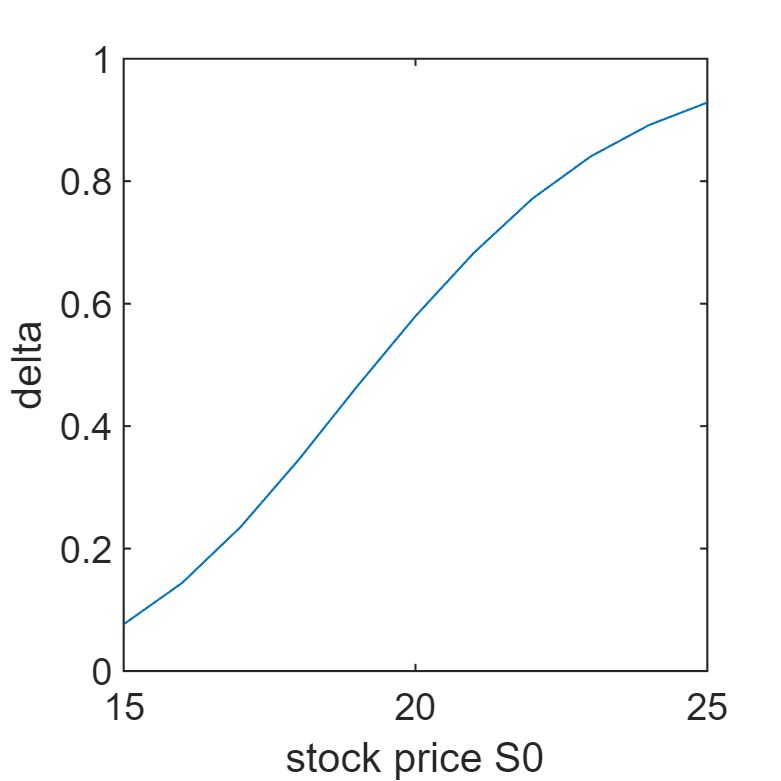

T=0.5; X=20; r=0.04; sigma=0.25; dt=0.004; delta = 0.01;
% delta
delta_vector = 1:10;
for S0 = 15:25
    delta_vector(S0-14) = call_price_MC(S0+delta, T, X, r, sigma, dt) - call_price_MC(S0-delta, T, X, r, sigma, dt);
    delta_vector(S0-14) = delta_vector(S0-14)/(2*delta);
end

x_axis_vector = 15:25;

plot(x_axis_vector,delta_vector)
xlabel('stock price S0') 
ylabel('delta') 

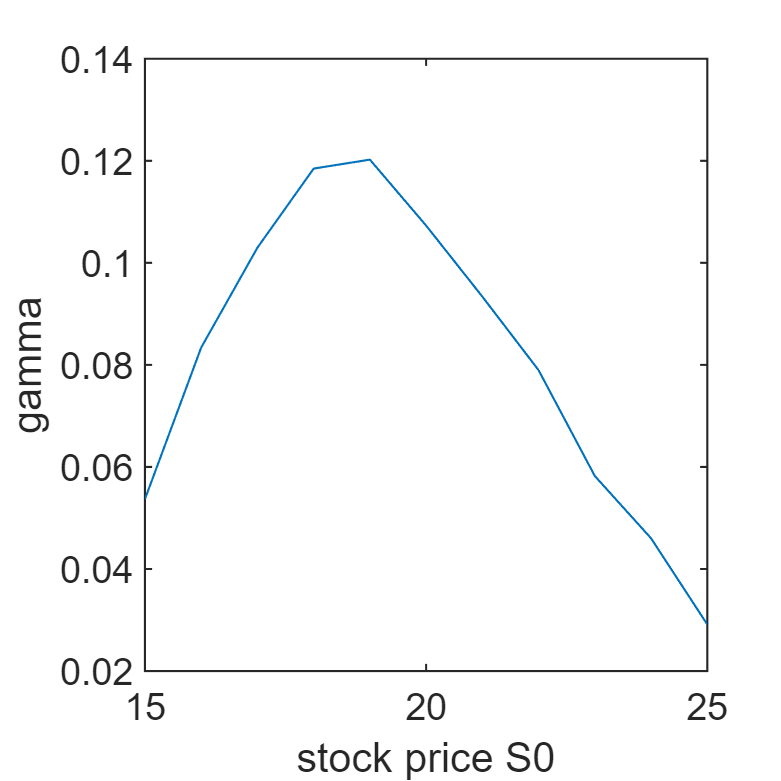

% gamma
gamma_vector = 1:10;
for S0 = 15:25
    % delta of S0+0.01
    delta1 = call_price_MC(S0+delta*2, T, X, r, sigma, dt) - call_price_MC(S0, T, X, r, sigma, dt);
    delta1 = delta1/(2*delta);
    % delta of S0-0.01
    delta2 = call_price_MC(S0, T, X, r, sigma, dt) - call_price_MC(S0-delta*2, T, X, r, sigma, dt);
    delta2 = delta2/(2*delta);
    gamma_vector(S0-14) = (delta1-delta2)/(2*delta);
end

x_axis_vector = 15:25;

plot(x_axis_vector,gamma_vector)
xlabel('stock price S0') 
ylabel('gamma') 

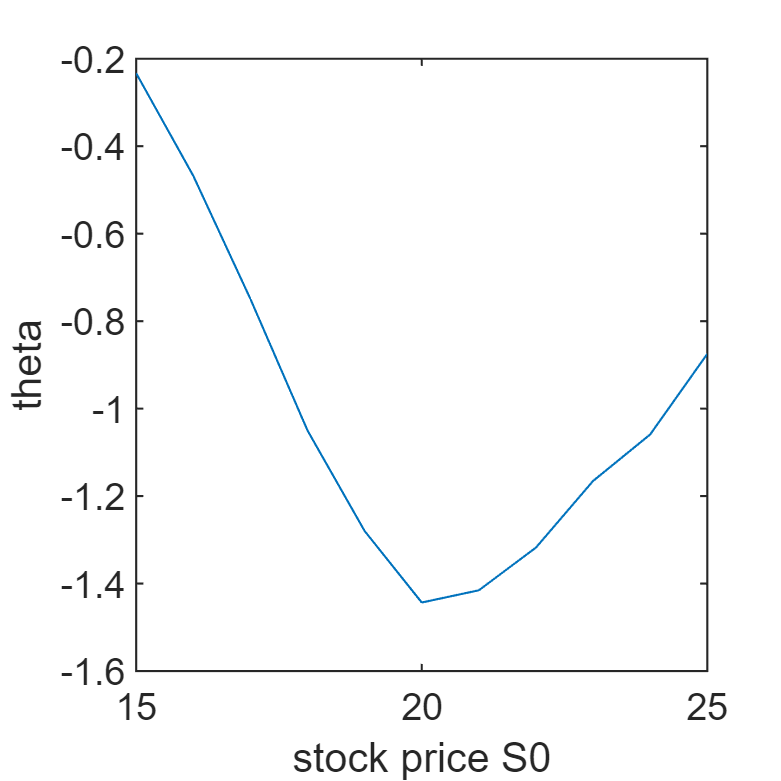

% theta
theta_vector = 1:10;
for S0 = 15:25
    % as time increase, the time to maturity decreases
    theta_vector(S0-14) = call_price_MC(S0, T-dt, X, r, sigma, dt) - call_price_MC(S0, T, X, r, sigma, dt);
    theta_vector(S0-14) = theta_vector(S0-14)/dt;
end

x_axis_vector = 15:25;

plot(x_axis_vector,theta_vector)
xlabel('stock price S0') 
ylabel('theta')

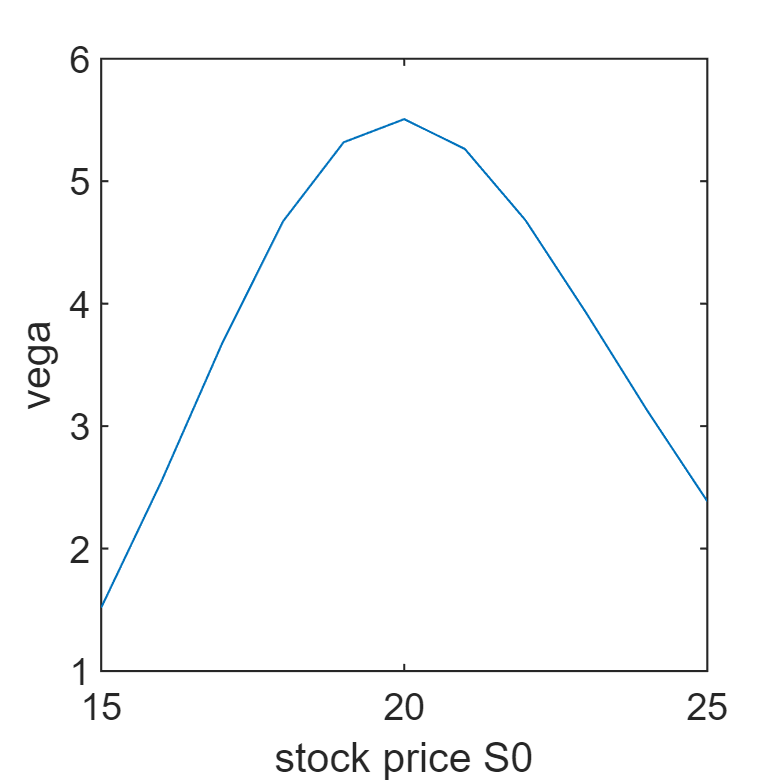

% vega
vega_vector = 1:10;
for S0 = 15:25
    vega_vector(S0-14) = call_price_MC(S0, T, X, r, sigma+delta, dt) - call_price_MC(S0, T, X, r, sigma-delta, dt);
    vega_vector(S0-14) = vega_vector(S0-14)/(2*delta);
end

x_axis_vector = 15:25;

plot(x_axis_vector,vega_vector)
xlabel('stock price S0') 
ylabel('vega')

**4. Consider the following 2-factor model for stock prices with stochastic volatility:**


$$\left\lbrace \begin{array}{ll}
dS_t  & =rS_t \textrm{dt}+\sqrt{V_t }S_t \;dW_t^1 \\
dV_t  & =\alpha \left(\beta -V_t \right)\textrm{dt}+\sigma \sqrt{V_t }dW_t^2 
\end{array}\right.$$


**where the Brownian Motion processes above are correlated: **$dW_t^1$$dW_t^2$** = **$\rho$dt**, where the correlation **$\rho$** is a constant in [-1,1]. **

**Estimate the price of a European Call option (via Monte Carlo simulation) that has a strike price of K and matures in T years.**

**Use the following default parameters of the model: **$\rho$** = -0.6, r = 0.03, **$S_0$** = $48, **$V_0$** = 0.05, 𝜎 =0.42, **$\alpha$** = 5.8, **$\beta$** = 0.0625.**

**Use the Full Truncation, Partial Truncation, and Reflection methods, and provide 3 price estimates by using the tree methods. ** 

rho = -0.6; r = 0.03; S0 = 48; V0 = 0.05; sigma = 0.42; alpha = 5.8; beta = 0.0625;
K = 50; T = 0.5; dt=0.004; n=100000;

% Wt
L = chol([1,rho;rho,1],'lower'); % cholesky decomposition

% set seed
%rng(170);
% Full Truncation
num_steps = T/dt;
St_vector = ones(num_steps+1,n); St_vector(1,:) = ones(1,n) * S0;
Vt_vector = ones(num_steps+1,n); Vt_vector(1,:) = ones(1,n) * V0;
for t = 1:num_steps
    Wt = normrnd(0,1,[2,n]);
    Wt = L*Wt;
    Wt1 = Wt(1,:);
    Wt2 = Wt(2,:);
    % dSt = rSt dt + sqrt(Vt)St dWt1
    St_vector(t+1,:) = St_vector(t,:) + r*St_vector(t,:) * dt + sqrt(max(Vt_vector(t,:),0)) .* St_vector(t,:) .* Wt1 * sqrt(dt);
    % dVt = alpha(beta-Vt) dt + sigma sqrt(Vt) dWt2
    Vt_vector(t+1,:) = Vt_vector(t,:) + alpha * (beta-max(Vt_vector(t,:),0)) * dt + sigma * sqrt(max(Vt_vector(t,:),0)) .* Wt2 * sqrt(dt);
end
mean(St_vector(num_steps+1,:))

ans = 48.7135

C1 = exp(-r*T) * mean(max(St_vector(num_steps+1,:)-K, 0),2)

C1 = 2.6087

% Partial Truncation
St_vector = ones(num_steps+1,n); St_vector(1,:) = ones(1,n) * S0;
Vt_vector = ones(num_steps+1,n); Vt_vector(1,:) = ones(1,n) * V0;
for t = 1:num_steps
    Wt = normrnd(0,1,[2,n]);
    Wt = L*Wt;
    Wt1 = Wt(1,:);
    Wt2 = Wt(2,:);
    % dSt = rSt dt + sqrt(Vt)St dWt1
    St_vector(t+1,:) = St_vector(t,:) + r*St_vector(t,:) * dt + sqrt(max(Vt_vector(t,:),0)) .* St_vector(t,:) .* Wt1 * sqrt(dt);
    % dVt = alpha(beta-Vt) dt + sigma sqrt(Vt) dWt2
    Vt_vector(t+1,:) = Vt_vector(t,:) + alpha * (beta-Vt_vector(t,:)) * dt + sigma * sqrt(max(Vt_vector(t,:),0)) .* Wt2 * sqrt(dt);
end

C2 = exp(-r*T) * mean(max(St_vector(num_steps+1,:)-K, 0),2)

C2 = 2.6236

% Reflection methods
St_vector = ones(num_steps+1,n); St_vector(1,:) = ones(1,n) * S0;
Vt_vector = ones(num_steps+1,n); Vt_vector(1,:) = ones(1,n) * V0;
for t = 1:num_steps
    Wt = normrnd(0,1,[2,n]);
    Wt = L*Wt;
    Wt1 = Wt(1,:);
    Wt2 = Wt(2,:);
    % dSt = rSt dt + sqrt(Vt)St dWt1
    St_vector(t+1,:) = St_vector(t,:) + r*St_vector(t,:) * dt + sqrt(abs(Vt_vector(t,:))) .* St_vector(t,:) .* Wt1 * sqrt(dt);
    % dVt = alpha(beta-Vt) dt + sigma sqrt(Vt) dWt2
    Vt_vector(t+1,:) = abs(Vt_vector(t,:)) + alpha * (beta-abs(Vt_vector(t,:))) * dt + sigma * sqrt(abs(Vt_vector(t,:))) .* Wt2 * sqrt(dt);
end

C3 = exp(-r*T) * mean(max(St_vector(num_steps+1,:)-K, 0),2)

C3 = 2.5903

**5. The objective of this exercise is to compare a sample of Pseudo-Random numbers with a sample of Quasi-Monte Carlo numbers of Uniform [0,1]x[0,1]:**

**a) Generate 100 2-dimensional Uniform [0,1]x[0,1] vectors by using any one of the algorithms for random number generation.**

U_vector = zeros(100,2);
U_vector(:,1) = generate_U(100,101).'; % generate one-demensional 100 uniformly random numbers with LGM methd
U_vector(:,2) = generate_U(100,7001).'; % generate one-demensional 100 uniformly random numbers with LGM methd
U_vector

U_vector =     0.0008    0.0548
    0.2901    0.2248
    0.9053    0.5368
    0.6098    0.2287
    0.4725    0.5310
    0.9067    0.2285
    0.2740    0.6935
    0.3845    0.5940
    0.7148    0.6146
    0.2195    0.9995


**b) Generate 100 points of the 2-dimensional Halton sequences, using bases 2 and 7.**

H_vector = zeros(100,2);
H_vector(:,1) = GetHalton(100, 2); % generate one-demensional Halton sequence with 100 numbers base 2
H_vector(:,2) = GetHalton(100, 7); % generate one-demensional Halton sequence with 100 numbers base 7
H_vector

H_vector =     0.5000    0.1429
    0.2500    0.2857
    0.7500    0.4286
    0.1250    0.5714
    0.6250    0.7143
    0.3750    0.8571
    0.8750    0.0204
    0.0625    0.1633
    0.5625    0.3061
    0.3125    0.4490


**c) Generate 100 points of the 2-dimensional Halton sequences, using bases 2 and 4. (Note: 4 is a nonprime number!).**

H2_vector = zeros(100,2);
H2_vector(:,1) = GetHalton(100, 2); % generate one-demensional Halton sequence with 100 numbers base 2
H2_vector(:,2) = GetHalton(100, 4); % generate one-demensional Halton sequence with 100 numbers base 4
H2_vector

H2_vector =     0.5000    0.2500
    0.2500    0.5000
    0.7500    0.7500
    0.1250    0.0625
    0.6250    0.3125
    0.3750    0.5625
    0.8750    0.8125
    0.0625    0.1250
    0.5625    0.3750
    0.3125    0.6250


**d) Draw all 3 sequences of random numbers on separate graphs. Are there differences in the three sets (visual test only)? Comment on your observations.**

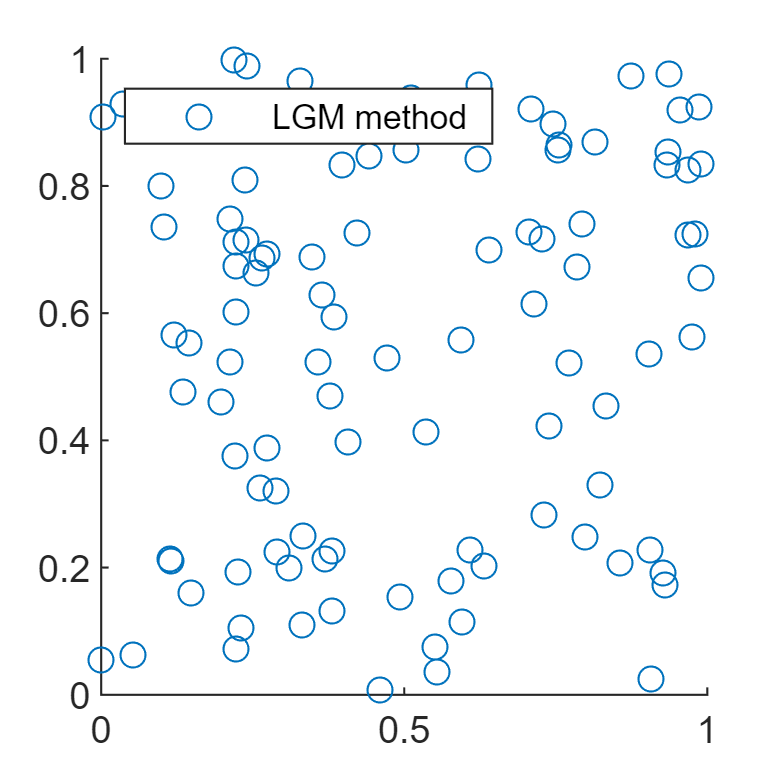

% 100 2-dimensional Uniform [0,1]x[0,1] vectors by using LGM method
scatter(U_vector(:,1),U_vector(:,2))
set(gcf,'Position',[250 250 250 250])
legend("LGM method",...
    'Location','northwest','NumColumns',1)

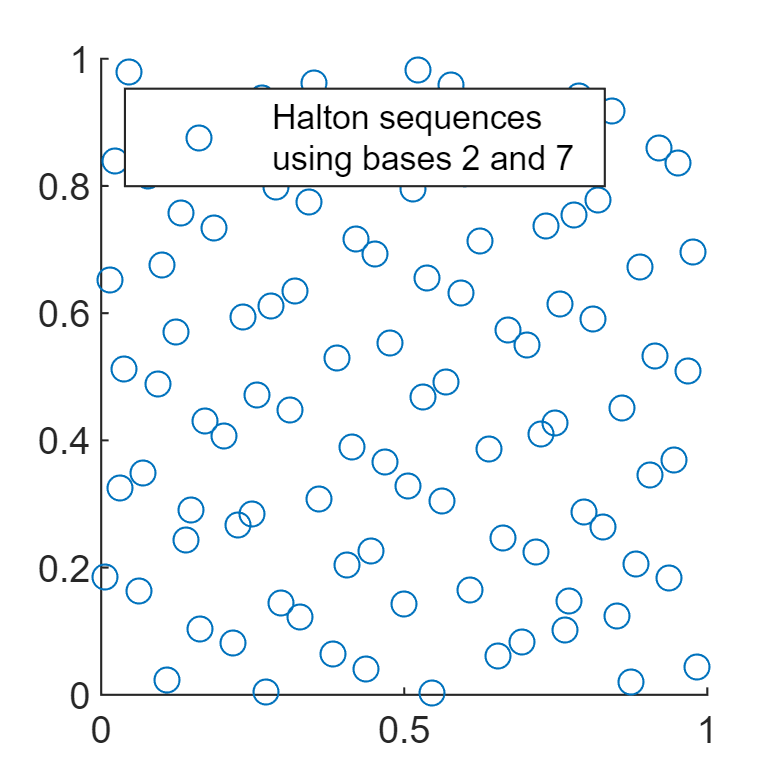

% 100 points of the 2-dimensional Halton sequences by using bases 2 and 7
scatter(H_vector(:,1),H_vector(:,2))
set(gcf,'Position',[250 250 250 250])
legend("Halton sequences " + newline + "using bases 2 and 7",...
    'Location','northwest','NumColumns',1)

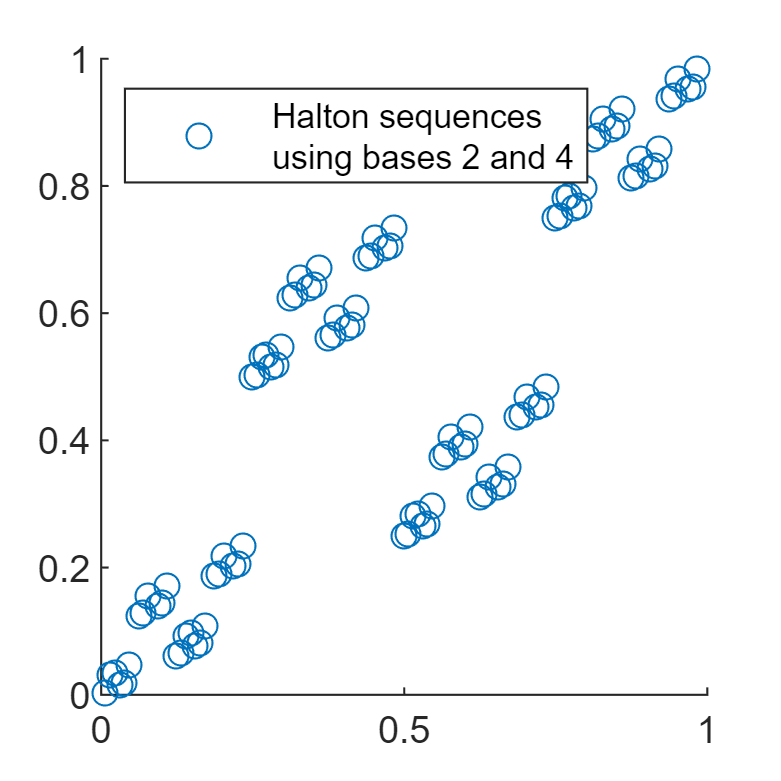

% 100 points of the 2-dimensional Halton sequences by using bases 2 and 4
scatter(H2_vector(:,1),H2_vector(:,2))
set(gcf,'Position',[250 250 250 250])
legend({"Halton sequences " + newline + "using bases 2 and 4"},...
    'Location','northwest','NumColumns',1)

Halton sequence by using two different prime numbers looks more "uniform random" than those generated from LGM method. But, in terms of the Halton sequence by using non-prime numbers, the points look highly correlated. So, generally, among these three methods, Halton sequence by using two different prime numbers have the best performance.

**e) Use 2-dimensional Halton sequences to compute the following integral:**

 
$$I=\int_0^1 \int_0^1 e^{-\textrm{xy}} \left(\sin \left(6\pi x\right)+\cos^{\frac{1}{3}} \left(2\pi y\right)\right)\textrm{dx}\textrm{dy}$$


**Use N=10,000 in your simulations. Try different couples for bases: (2,4), (2,7), (5,7).  **

% bases are (2,4)
x = GetHalton(10000, 2); % generate one-demensional Halton sequence with 10000 numbers base 2
y = GetHalton(10000, 4); % generate one-demensional Halton sequence with 10000 numbers base 4
sim = exp(-x.*y).*(sin(6*pi*x)+nthroot(cos(2*pi*y),3));
I = mean(sim,1)

I = -0.0049

% bases are (2,7)
x = GetHalton(10000, 2); % generate one-demensional Halton sequence with 10000 numbers base 2
y = GetHalton(10000, 7); % generate one-demensional Halton sequence with 10000 numbers base 7
sim = exp(-x.*y).*(sin(6*pi*x)+nthroot(cos(2*pi*y),3));
I = mean(sim,1)

I = 0.0261

% bases are (5,7)
x = GetHalton(10000, 5); % generate one-demensional Halton sequence with 10000 numbers base 5
y = GetHalton(10000, 7); % generate one-demensional Halton sequence with 10000 numbers base 7
sim = exp(-x.*y).*(sin(6*pi*x)+nthroot(cos(2*pi*y),3));
I = mean(sim,1)

I = 0.0262

function call_price = call_price_MC(S0, T, X, r, sigma, dt)
    % compute call price with Monte Carlo Simultion
    n=100000;
    % set seed
    rng(21);
    % Antithetic Variates
    %Wt
    WT = sum(normrnd(0,sqrt(dt),[T/dt,n]),1);
    % St
    ST_pos = S0 * exp(sigma*WT + (r-sigma^2/2)*T);
    ST_neg = S0 * exp(sigma*(-WT) + (r-sigma^2/2)*T);
    % call price
    C1_pos = exp(-r*T)*max(ST_pos-X, 0);
    C1_neg = exp(-r*T)*max(ST_neg-X, 0);
    call_price = mean((C1_pos+C1_neg)/2,2);
end

function N_x=Nx_generate(x)
    % generate N(.) with numerical methods
    % N(x) = 1-N(-x) if x < 0
    % N(x) = 1-1/2*(1+d1*x+d2*x^2+d3*x^3+d4*x^4+d5*x^5+d6*x^6)^(-16) if x >= 0
    N_x=(x<0)+sign(x)*Nx_pos_generate(sign(x)*x);
end

function N_x=Nx_pos_generate(x)
    % generate N(.) with numerical methods under positive x condition
    % N(x) = 1-1/2*(1+d1*x+d2*x^2+d3*x^3+d4*x^4+d5*x^5+d6*x^6)^(-16) if x >= 0
    d1 = 0.0498673470; d2 = 0.0211410061; d3 = 0.0032776263;
    d4 = 0.0000380036; d5 = 0.0000488906; d6 = 0.0000053830;
    N_x = 1 - 1/2 * (1+d1*x+d2*(x.^2)+d3*(x.^3)+d4*(x.^4)+d5*(x.^5)+d6*(x.^6)).^(-16);
end

function U_vector = generate_U(num, seed) 
    % generate num uniformly distributed numbers in [0,1] 
    m = pow2(31)-1;
    a = power(7,5)+3;
    X_vector = 1:num;
    for i = 1:num
        if i == 1
            % use 1 as X_0
            X_vector(i) = mod(a*seed,m);
        else
            % generate next X based on current X
            X_vector(i) = mod(a*X_vector(i-1),m);
        end
    end
    % divide X by m
    U_vector = X_vector/m;
end

function Seq = GetHalton(HowMany, Base)
    % generate one demensional Helton Sequence
    % note: adopted from Brandimartets "Numerical methods in finance and economics: a MATLAB-based introduction"
    Seq = zeros(HowMany,1);
    % NumBits = m+1
    % m^r <= HowMany < m^(r+1) So, r <= log(HowMany)/log(Base) < r+1
    NumBits = 1+ceil(log(HowMany)/log(Base));
    VetBase = Base.^(-(1:NumBits));
    WorkVet = zeros(1,NumBits);
    for i=1:HowMany
        j=1;
        ok = 0; % ok is a flag
        while ok == 0
            WorkVet(j) = WorkVet(j)+1;
            if WorkVet(j) < Base
                ok = 1;
            else
                WorkVet(j) = 0;
                j = j+1;
            end
        end
        Seq(i) = dot(WorkVet,VetBase);
    end
end